### First use my algorithm to make gff3 file

fastafile = 'Vibrio_vulnificus.ASM74310v1.dna.toplevel.fa';
configFile = 'configurations.xlsx';
outputFile = 'vulnificusOutput.gff3';
Viterbi(fastafile, configFile, outputFile);

### Read the two gff3 files

% fasta file
filename = 'Vibrio_vulnificus.ASM74310v1.dna.toplevel.fa';
reads = fastaread(filename);
info = fastainfo(filename);

% my file
myGFF = GFFAnnotation('vulnificus2.gff3');

% real file
realGFF = GFFAnnotation('Vibrio_vulnificus.ASM74310v1.37.gff3');


% some required info
N = info.NumberOfEntries;
refNamesMine = getReferenceNames(myGFF);
refNamesReal = getReferenceNames(realGFF);

numRefs = length(refNamesMine);
numRefs2 = length(refNamesReal);

### Get fractions of annotated genes that match mine

totalGenes = 0;
matchStart = 0;
matchStop = 0;
matchBoth = 0;
numMissed = 0;
totalLengthMissed = 0;

missedStartByHowMuch = [];
lengthOfMissed = [];

% for every reference name
for n = 1:numRefs2
    realAnnots = getData(realGFF,'Reference',refNamesReal(n),'Feature','CDS');
    positiveStrands = realAnnots(startsWith({realAnnots.Strand}, '+'));
    numRealGenes = length(positiveStrands);
    
    myAnnots = getData(myGFF,'Reference',refNamesReal(n),'Feature','CDS');
    numMyGenes = length(myAnnots);
    
    totalGenes = totalGenes + numRealGenes;
    for x = 1:numRealGenes
        start = positiveStrands(x).Start;
        stop = positiveStrands(x).Stop;
        
        match = false;
        for j = 1:numMyGenes
            start2 = myAnnots(j).Start;
            stop2 = myAnnots(j).Stop;
            if (start == start2) && (stop == stop2)
                match = true;
                matchBoth = matchBoth + 1;
                break;
            elseif start == start2
                match = true;
                matchStart = matchStart + 1;
                break;
            elseif stop == stop2
                l = abs(start2-start);
                missedStartByHowMuch = [missedStartByHowMuch; l];
                match = true;
                matchStop = matchStop + 1;
                break;
            end
        end
        if match == false
            l = stop-start;
            lengthOfMissed = [lengthOfMissed; l];
        end
    end
end
totalGenes

totalGenes = 2443




matchBoth

matchBoth = 1461

matchBothPercent = matchBoth / totalGenes

matchBothPercent = 0.5980


neither = totalGenes - matchStart - matchStop - matchBoth;

matchStart

matchStart = 0

matchStartPercent = matchStart / totalGenes

matchStartPercent = 0


matchStop

matchStop = 680

matchStopPercent = matchStop / totalGenes

matchStopPercent = 0.2783

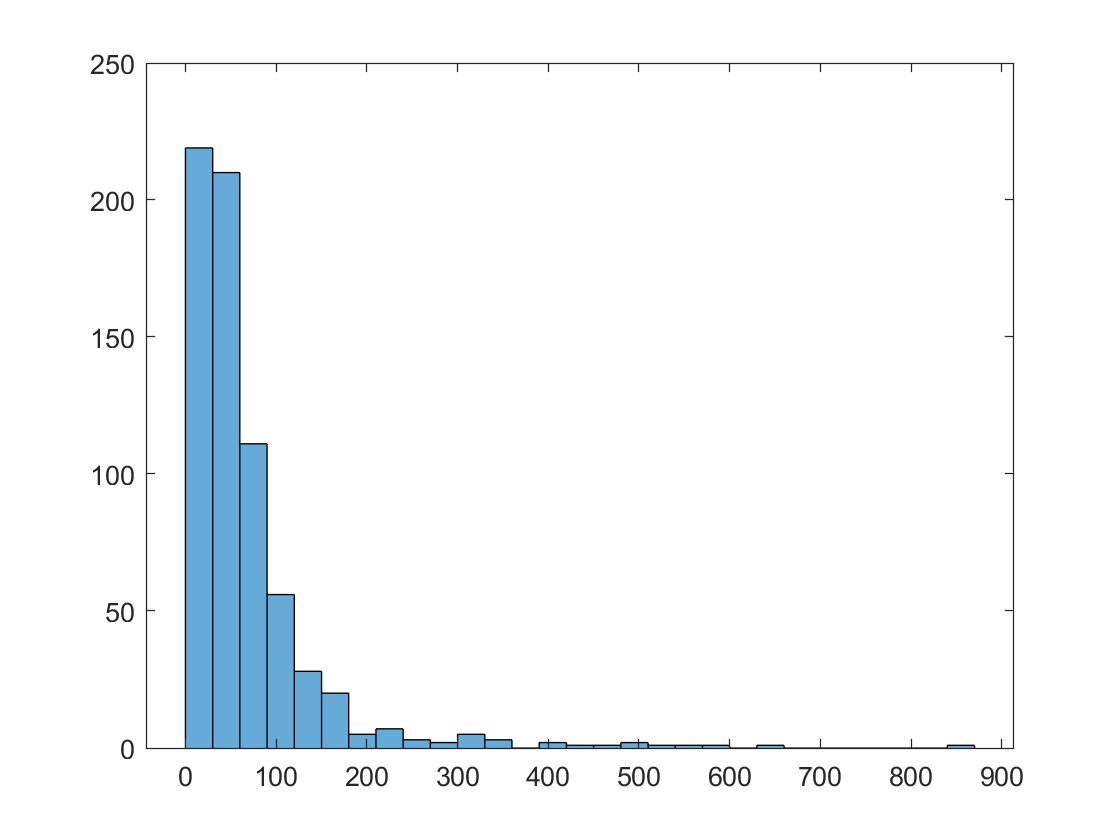

h =   Histogram with properties:

             Data: [680×1 int32]
           Values: [219 210 111 56 28 20 5 7 3 2 5 3 0 2 1 1 2 1 1 1 0 1 0 0 0 0 0 0 1]
          NumBins: 29
         BinEdges: [0 30 60 90 120 150 180 210 240 270 300 330 360 390 420 450 480 510 540 570 600 630 660 690 720 750 780 810 840 870]
         BinWidth: 30
        BinLimits: [0 870]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties



h = histogram(missedStartByHowMuch)


neither

neither = 302

neitherPercent = neither / totalGenes

neitherPercent = 0.1236

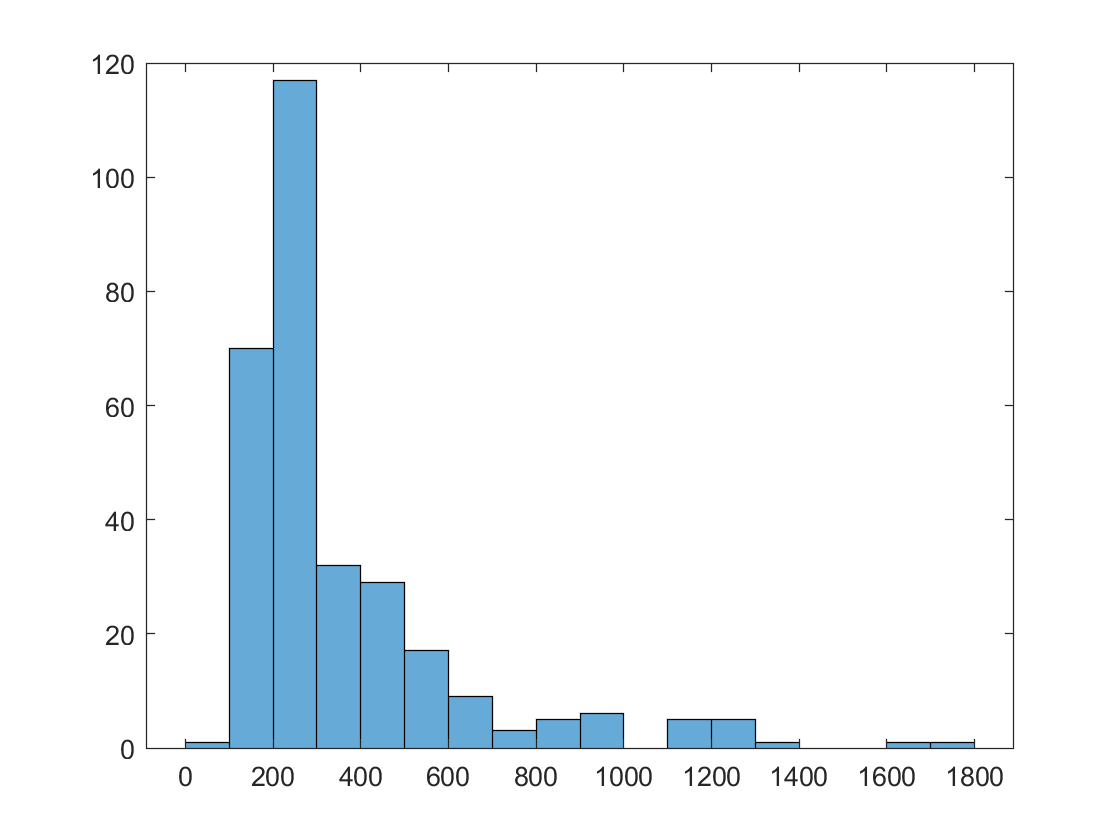

h =   Histogram with properties:

             Data: [302×1 int32]
           Values: [1 70 117 32 29 17 9 3 5 6 0 5 5 1 0 0 1 1]
          NumBins: 18
         BinEdges: [0 100 200 300 400 500 600 700 800 900 1000 1100 1200 1300 1400 1500 1600 1700 1800]
         BinWidth: 100
        BinLimits: [0 1800]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties



h = histogram(lengthOfMissed)

### Get fractions of my genes that match annotated

totalGenes = 0;

% for every reference name
for n = 1:numRefs
    myAnnots = getData(myGFF,'Reference',refNamesMine(n),'Feature','CDS');
    numMyGenes = length(myAnnots);
    
    totalGenes = totalGenes + numMyGenes;
   
end
totalGenes

totalGenes = 2689

neither = totalGenes - matchStart - matchStop - matchBoth;
matchStart

matchStart = 0

matchStartPercent = matchStart / totalGenes

matchStartPercent = 0

matchStop

matchStop = 680

matchStopPercent = matchStop / totalGenes

matchStopPercent = 0.2529

matchBoth

matchBoth = 1461

matchBothPercent = matchBoth / totalGenes

matchBothPercent = 0.5433

neither

neither = 548

neitherPercent = neither / totalGenes

neitherPercent = 0.2038